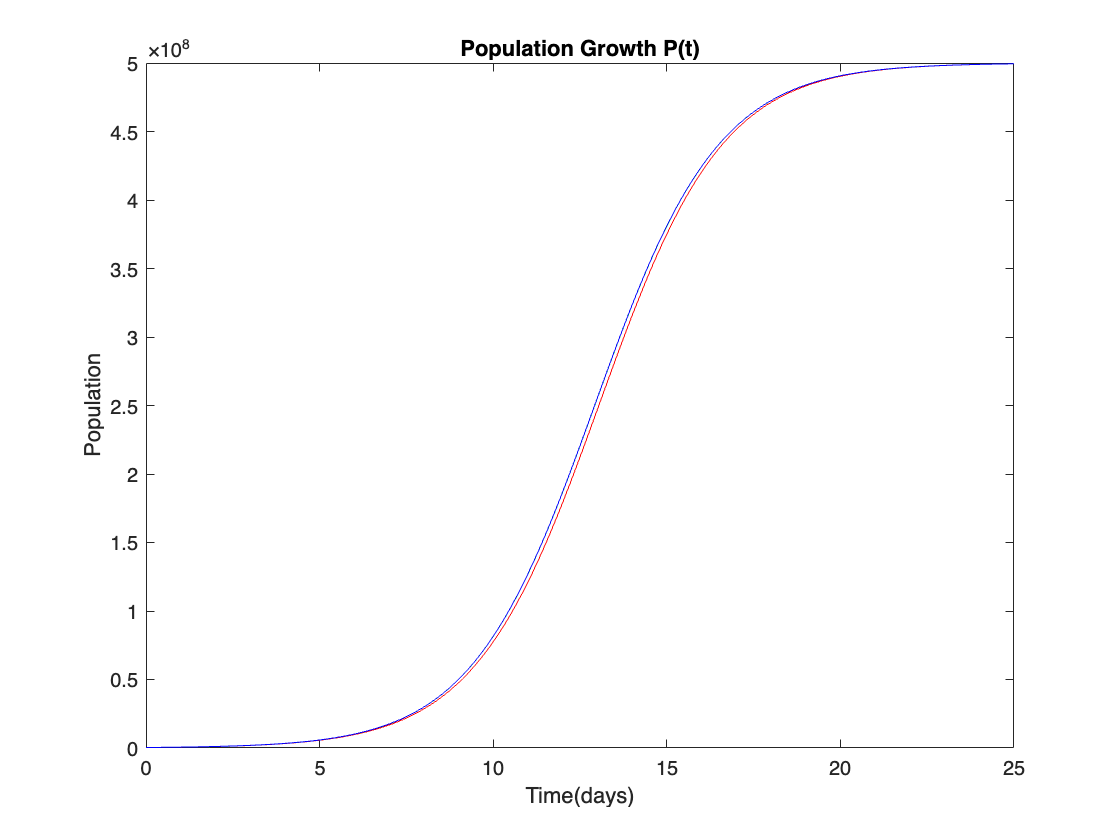

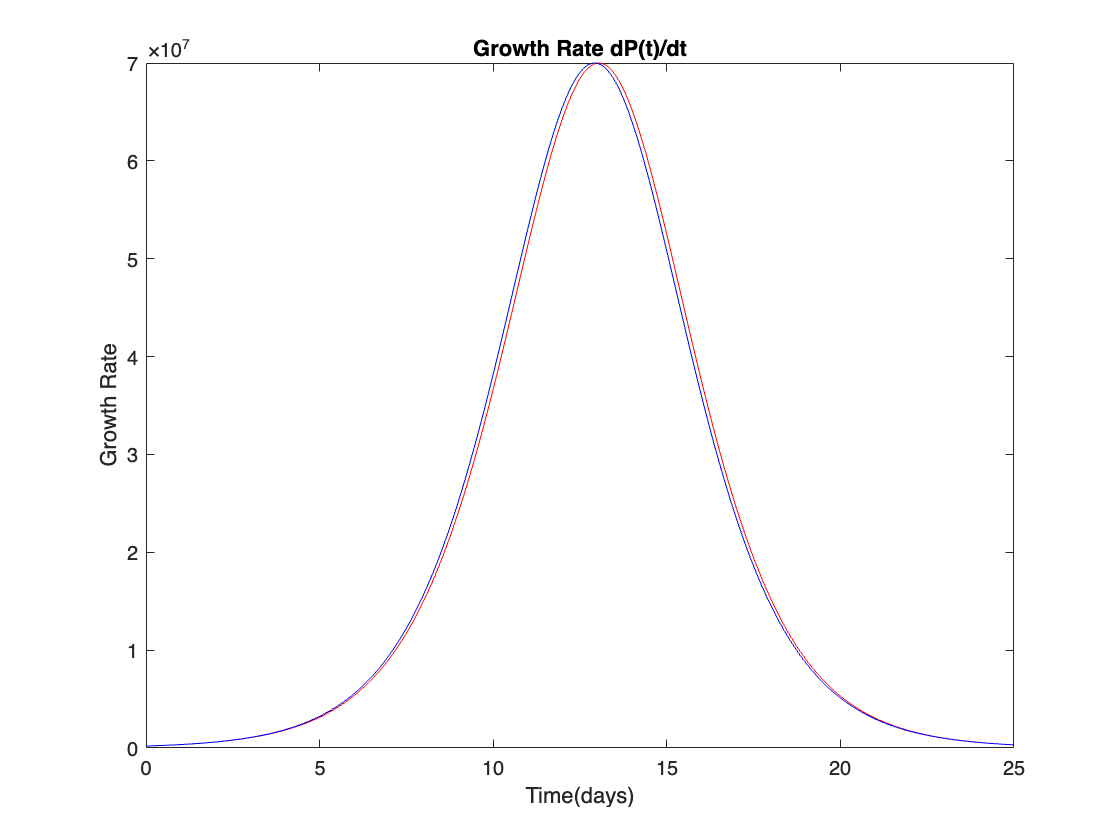

r=0.56;
k=5E8;
P0=3000*120;
total_days=25;

dt_values=[1/24,1/1440,1/86400];
colors=['r','g','b'];
pop_at_3_days=zeros(length(dt_values),1);
f1=figure; f2=figure;
for i=1:length(dt_values)
    dt=dt_values(i);
    num_steps=ceil(total_days/dt);
    t=(0:num_steps)*dt;
    P=zeros(size(t));
    P(1)=P0;

    for n=1:num_steps
        dPdt=r*P(n)*(1-P(n)/k);
        P(n+1)=P(n)+dPdt*dt;
        if dt*n==3
            pop_at_3_days(i)=P(n);
        end
            
    end
    

    figure(f1)
    plot(t,P,colors(i))
    hold on;
    title('Population Growth P(t)')
    xlabel('Time(days)')
    ylabel('Population')
  
  

    figure(f2)
    dPdt=r*P.*(1-P/k);
    plot(t,dPdt,colors(i));
    hold on;
    title('Growth Rate dP(t)/dt');
    xlabel('Time(days)'); ylabel('Growth Rate');
  

end


% smallest_dt_pop=pop_at_3_days(end)
PCT_errors=abs((pop_at_3_days(1:end-1)-pop_at_3_days(end)))/pop_at_3_days(end)*100;
fprintf ('For dt=1/24 the error is %1.4f %% \n',PCT_errors(1));

For dt=1/24 the error is 4.1251 % 


fprintf('For dt= 1/1440 the error is %1.4f %% \n',PCT_errors(2));

For dt= 1/1440 the error is 0.0699 % 
